## B: Poisson Distribution, Estimates

### Why is this a Poisson distribution?

- Independent events (unless there's a gang)

- Bikes occupy physical space, two bikes cannot pass the same spot in the same instant

- Has a ratio of expected number of events per time unit

### Calculating Lambda


$$\hat{\lambda} = \frac{X}{t}$$


lambda = 78 / 30

lambda = 2.6000


$$Var(X)=\lambda t$$


variance = lambda * 30

variance = 78

%variance = total;


$$\hat{\sigma} = \sqrt{Var(X)} = \sqrt{\lambda t}$$


standard_deviation = sqrt(variance)

standard_deviation = 8.8318


$$\hat{\mu} = \hat{\lambda} \cdot t = \frac{X}{t}\cdot t = X$$


forventning = 78

forventning = 78


$$P(X = x) = \frac{(\lambda t)^x}{x!} e^{-\lambda t}$$



$$P(X > \mu + \sigma) = 1 - P(X \le \mu + \sigma)$$


P = @(x) exp(-78)*78^x / factorial(x)

P = function_handle with value:
    @(x)exp(-78)*78^x/factorial(x)


standard_deviation + forventning

ans = 86.8318

limit = round(forventning + standard_deviation, 0, "decimals")

limit = 87

p = 1;
for i=0:limit - 1
    p = p - P(i);
end
sprintf('The probability is %f', p)

ans = 'The probability is 0.167454'

### Graphs

#### With t = 1 minute

– lower reliability

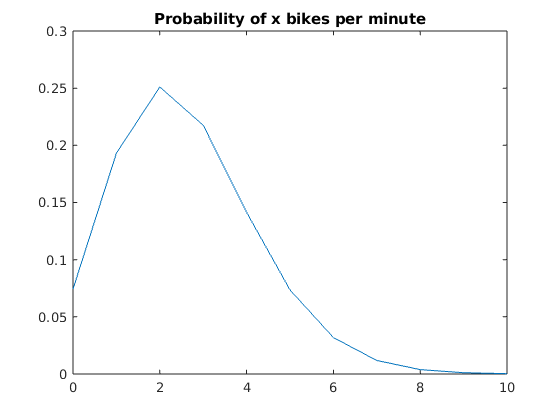

x = 0:10;
plot(x, poisspdf(x,lambda))
title('Probability of x bikes per minute')

#### With t = 30 minutes

– which matches the circumstances of our original data


$$\hat{\lambda} \cdot t = \frac{x}{t}\cdot t = x$$


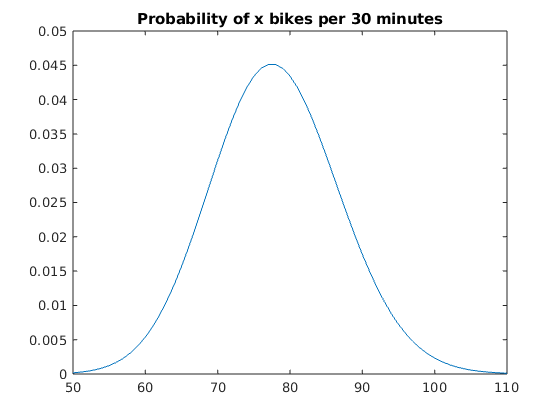

x = 50:110;
plot(x, poisspdf(x,78))
title('Probability of x bikes per 30 minutes')